# **Build a Battery Pack Model with 6p X 96s Cell Configuration**

To use the functions and objects in Simscape Battery, first import the required Simscape Battery package:

import simscape.battery.builder.*

## Create Battery Pack Object in MATLAB

To create a battery pack, you must first design and create the foundational elements of the battery pack.

This figure shows the overall process to create a battery pack object in a bottom-up approach:

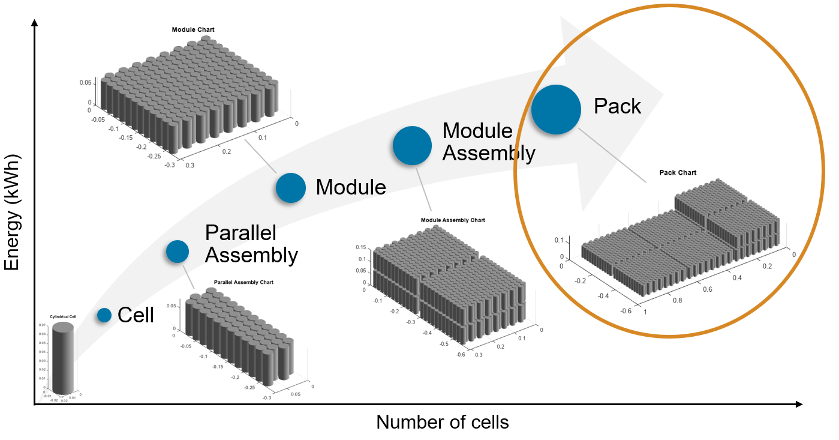

A battery pack comprises multiple module assemblies. These module assemblies, in turn, comprise a number of battery modules connected electrically in series or in parallel. The battery modules are made of multiple parallel assemblies which, in turn, comprise a number of battery cells connected electrically in parallel under a specific topological configuration or geometrical arrangement.

### Create Cell Object

To create the battery `Module` object, first create a `Cell` object of cylindrical format. We will use  INR21700 Samsung50G cells.

Cell Height is 70.15 mm, which is 0.07015 m. Cell max diameter is 21.10 mm, or max radius is 10.55 mm, which is 0.01055 m. 

import simscape.battery.builder.*

cylindricalGeometry = CylindricalGeometry(Height = simscape.Value(0.07015,"m"),...
    Radius = simscape.Value(0.01055,"m"));

The CylindricalGeometry object allows you to define the cylindrical geometrical arrangement of the battery cell. You can specify the height, length, and location of tabs of the cell by setting the **Height**,** Length**, and** TabLocation** properties of the `CylindricalGeometry` object. For more information on the possible geometrical arrangements of a battery cell, see the [CylindricalGeometry](docid:battery_ref#mw_c5224532-2b73-4d0f-b268-6be8da8acd16) and [PrismaticGeometry](docid:battery_ref#mw_ec08796b-482d-4e27-8ada-0dd1efd7a1af) documentation pages.

Now use this `CylindricalGeometry` object to create a battery cell.

batteryCell = Cell(Geometry = cylindricalGeometry);

For more information, see the [Cell](docid:battery_ref#mw_2d026fef-ba0c-4c1a-92e1-11623b831691) documentation page. 

Cell weight is 69.5 g, which is 0.0695 kg.

batteryCell.CellModelOptions.BlockParameters.T_dependence = "yes";
batteryCell.CellModelOptions.BlockParameters.thermal_port = "model";
batteryCell.CellModelOptions.BlockParameters.prm_dyn = "off";
batteryCell.CellModelOptions.BlockParameters.prm_dir = "noCurrentDirectionality";
batteryCell.Mass = simscape.Value(0.0695,"kg");

### Create ParallelAssembly Object

A battery parallel assembly comprises multiple battery cells connected electrically in parallel under a specific topological configuration or geometrical arrangement. In this example, you create a parallel assembly of 34 pouch cells. 

To create the ParallelAssembly object, use the `Cell` object you created before and specify the **NumParallelCells **property according to your design.

import simscape.battery.builder.*

batteryParallelAssembly = ParallelAssembly(Cell = batteryCell, ...
    NumParallelCells = 34, ...
    Rows = 34, ...
    Topology = "Hexagonal", ...
    CoolingPlate="Bottom", ...
    ModelResolution = "Lumped");

For more information, see the [ParallelAssembly](docid:battery_ref#mw_a3e68eac-4afa-4391-b3ee-d464d818e28d) documentation page.

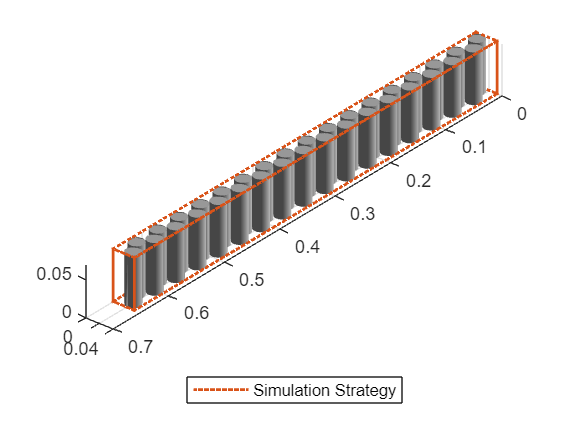

batteryParallelAssemblyChart = BatteryChart(Battery = batteryParallelAssembly, ...
    SimulationStrategyVisible = "on");

### Create Module Object

A battery module comprises multiple parallel assemblies connected in series. In this example, you create a battery module of 3 parallel assemblies with an intergap between each assembly of 0.005 meters.

To create the `Module` object, use the `ParallelAssembly` object you created in the previous step and specify the **NumSeriesAssemblies** and **InterParallelAssemblyGap** properties.

import simscape.battery.builder.*

batteryModule = Module(ParallelAssembly = batteryParallelAssembly,...
    NumSeriesAssemblies = 3, ...
    ModelResolution ="Grouped", ...
    SeriesGrouping = [1 1 1], ...
    InterParallelAssemblyGap = simscape.Value(0.005,"m"), ...
    AmbientThermalPath = "CellBasedThermalResistance", ...
    CoolantThermalPath = "CellBasedThermalResistance", ...
    CoolingPlate = "Bottom", ...
    BalancingStrategy = "Passive");

For more information, see the [Module](docid:battery_ref#mw_7667d6f8-0894-4334-b1b0-07b10449021a) documentation page.

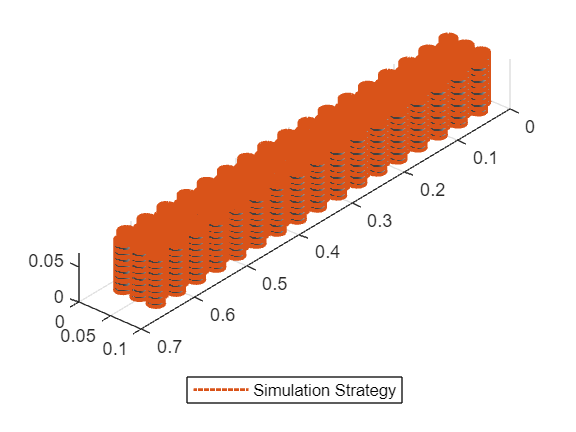

batteryModuleChart = BatteryChart(Battery = batteryModule, ...
    SimulationStrategyVisible = "on");

### Create ModuleAssembly Object

A battery module assembly comprises multiple battery modules connected in series or in parallel. In this example, you create a battery module assembly of two identical modules with an intergap between each module equal to 0.1 meters. The first three module assembies have 9 moudules in each module assembly and the last module assembly has 8 modules. So, there are a total of 4 module assemblies. By default, the `ModuleAssembly` object electrically connects the modules in series.

To create the `ModuleAssembly` object, use the `Module` object you created in the previous step and specify the **InterModuleGap** property.

import simscape.battery.builder.*

% Create 4 module assemblies with custom number of modules
% Create one module assembly with 9 modules in series
modAssy1 = ModuleAssembly(Module = repmat(batteryModule, 1, 9), ...
    CoolantThermalPath = "CellBasedThermalResistance", ...
    InterModuleGap = simscape.Value(0.01, "m"), ...
    CircuitConnection = "Series");

For more information, see the [ModuleAssembly](docid:battery_ref#mw_a7e69edd-6e39-41fa-b32b-b94ef3ffdc0f) documentation page.

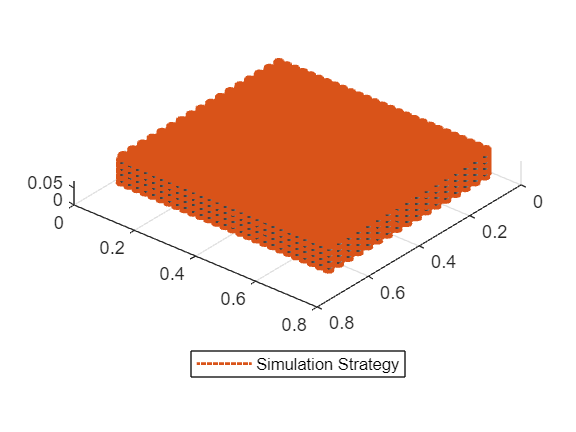

batteryModuleAssemblyChart = BatteryChart(Battery = modAssy1, ...
    SimulationStrategyVisible = "on");

The other 3 module assemblies.

% The rest of the module assemblies
modAssy2 = ModuleAssembly(Module = repmat(batteryModule, 1, 9), ...
    CoolantThermalPath = "CellBasedThermalResistance", ...
    InterModuleGap = simscape.Value(0.01, "m"), ...
    CircuitConnection = "Series");

modAssy3 = ModuleAssembly(Module = repmat(batteryModule, 1, 9), ...
    CoolantThermalPath = "CellBasedThermalResistance", ...
    InterModuleGap = simscape.Value(0.01, "m"), ...
    CircuitConnection = "Series");

modAssy4 = ModuleAssembly(Module = repmat(batteryModule, 1, 8), ...
    CoolantThermalPath = "CellBasedThermalResistance", ...
    InterModuleGap = simscape.Value(0.01, "m"), ...
    CircuitConnection = "Series");


Visualize the last module assembly, since it is different.

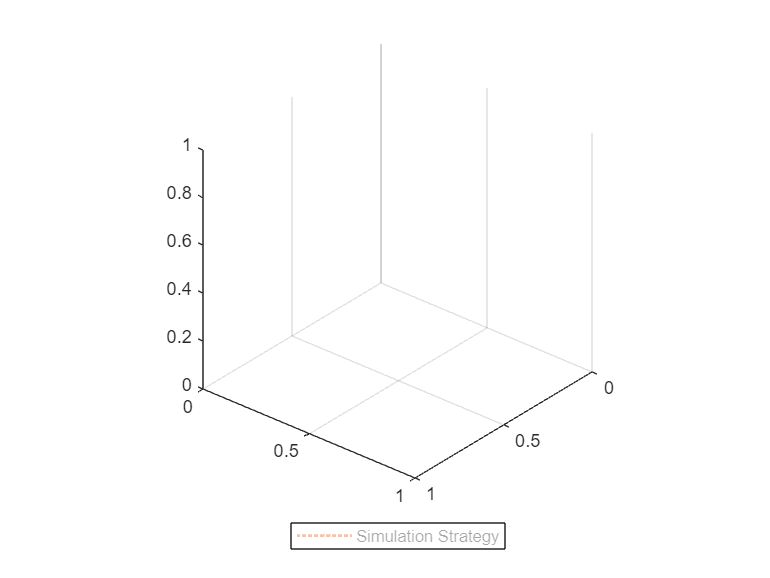

batteryModuleAssemblyChart = BatteryChart(Battery = modAssy4, ...
    SimulationStrategyVisible = "on");

### Create Pack Object

You now have all the foundational elements to create your battery pack. A battery pack comprises multiple module assemblies connected in series or in parallel. In this example, you create a battery pack of 4 previously built module assemblies with an intergap between each module assembly of 0.01 meters.

To create the `Pack` object, use the `ModuleAssembly` object you created in the previous step and specify the **InterModuleAssemblyGap** property.

import simscape.battery.builder.*

batteryPack = Pack(ModuleAssembly = [modAssy1, modAssy2, modAssy3, modAssy4], ...
    Name = "EV_BatteryPack", ... 
    InterModuleAssemblyGap = simscape.Value(0.01,"m"), ...
    CoolantThermalPath="CellBasedThermalResistance", ...
    BalancingStrategy = "Passive", ...
    CircuitConnection = "Series");

For more information, see the [Pack](docid:battery_ref#mw_733fa856-2f6d-4d21-abdd-e65b3e04e90a) documentation page.

## Visualize Battery Pack and Check Model Resolution

To obtain the number of Simscape Battery(Table-Based) blocks used for the pack simulation, use the **NumModels** property of your `Pack` object.

disp(batteryPack.NumModels);

        3570



To visualize the battery pack before you build the system model and to view its model resolution, use the `BatteryChart` object. 

Then use the `BatteryChart` object to visualize the battery pack. To view the model resolution of the module, set the **SimulationStrategyVisible** property of the `BatteryChart` object to `"On"`.

batteryPackChart = BatteryChart(Parent = uifigure, Battery = batteryPack, ...
    SimulationStrategyVisible = "on");

To add default axis labels to the battery plot, use the `setDefaultLabels` method of the `BatteryChart` object.

For more information, see the [BatteryChart](docid:battery_ref#mw_dbe5f15f-3424-47d4-8766-393cc212cfa7) documentation page.

## Build Simscape Model for the Battery Pack Object

After you have created your battery objects, you need to convert them into Simscape models to be able to use them in block diagrams. You can then use these models as reference for your system integration and requirement evaluation, cooling system design, control strategy development, hardware-in-the-loop, and much more.

To create a library that contains the Simscape Battery model of the `Pack` object you created in this example, use the `buildBattery` function.

To solve issue, create a new simulink project in the C:\Users\OWNER\Downloads\BatteryManagementSystemJuly11_Version3 directory. The command is

proj = simulinkproject('C:\Users\OWNER\Downloads\BatteryManagementSystemJuly11_Version3\Battery Management System');

proj = simulinkproject;

import simscape.battery.builder.*
proj = simulinkproject;
buildBattery(batteryPack, LibraryName = "BatteryPack_105s34p_Library", ...
    Directory = [proj.RootFolder,'\DesignBatteryPack'], ...
    MaskParameters ="VariableNames", MaskInitialTargets="VariableNames");

Generating Simulink library 'BatteryPack_105s34p_Library_lib' in the current directory 'C:\Users\OWNER\Downloads\BatteryManagementSystemJuly11_Version3\Battery Management System\DesignBatteryPack' ...
Generating MATLAB script 'BatteryPack_105s34p_Library_param' in the current directory 'C:\Users\OWNER\Downloads\BatteryManagementSystemJuly11_Version3\Battery Management System\DesignBatteryPack'


This function creates the `packLibrary_lib` and `packLibrary` SLX library files in your working directory. The `packLibrary_lib` library contains the Modules and ParallelAssemblies sublibraries. 

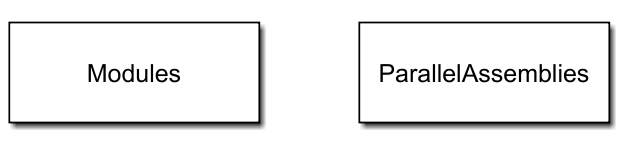

To access the Simscape models of your M`odule` and `ParallelAssembly` objects, open the `packLibrary_lib`. SLX file, double-click the sublibrary, and drag the Simscape blocks in your model. 

Use the following to Command Window to add the library package to MATLAB path because it is not automatically added. Basically, we need to add the full path of DesignBatteryPack folder.

addpath("C:\Users\OWNER\Downloads\BatteryManagementSystemJuly11_Version3\Battery Management System\DesignBatteryPack");
rehash;

The `packLibrary` library contains the Simscape models of your `ModuleAssembly` and `Pack` objects.

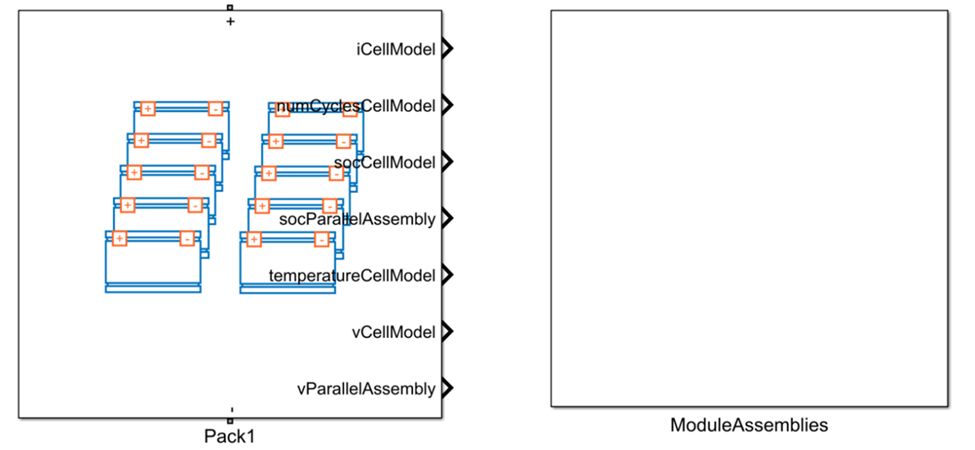

The Simscape models of your `ModuleAssembly` and `Pack` objects are subsystems. You can look inside these subsystems by opening the `packLibrary` SLX file and double-click the subsystem.

To learn how to include thermal effects in a battery pack, see the [Build Model of Battery Module with Thermal Effects](docid:battery_ug#example-batt_build_battery_module_thermal_effeects) example.

To build a more detailed model of a battery pack, see the [Build Detailed Model of Battery Pack From Pouch Cells](docid:battery_ug#example-batt_build_battery_pack_from_pouch_cells) example.

To learn how to model a battery energy storage system (BESS) controller and a battery management system (BMS) with all the necessary functions for the peak shaving, see the [Peak Shaving with Battery Energy Storage System](docid:battery_ug#example-batt_peak_shaving_with_bess) example. 

*Copyright 2022 The MathWorks, Inc.*